clear
m1=3; %massa corpo 1
m2=4; %massa carrello 2
m3=2; %massa carrello 3
m=0.2; %massa pulegga
k1=0.5; %0.5;
k2=0.5;
k3=0.5;
b2=0.4;
b3=0.4;
rm=0.2;
M=(m2+0.5*m); %M=1/(m2+0.5*m);
a=20;
g=9.81;

A=[0       1    0                  0        0    0
    -k1/m1 0  k1/m1                0        0    0
    0      0    0                  1        0    0
    k1/M   0  -(k1+k2+k3)/M   -(b2+b3)/M  k3/M  b3/M
    0      0    0                  0        0    1
    0      0    k3/m3           b3/m3    -k3/m3 -b3/m3];
B=[0            0       0
  sin(a)   sin(a)/m1    0
    0           0       0
    0           0       0
    0           0       0
    0           0       1];
C=[1 0 0 0 0 0
   0 0 1 0 0 0
   0 0 0 0 1 0];
D=[0 0 0; 0 0 0;0 0 0];

sys=ss(A,B,C,D);
eig(sys)

ans =   -0.1465 + 0.6992i
  -0.1465 - 0.6992i
  -0.0347 + 0.4599i
  -0.0347 - 0.4599i
  -0.0164 + 0.2157i
  -0.0164 - 0.2157i


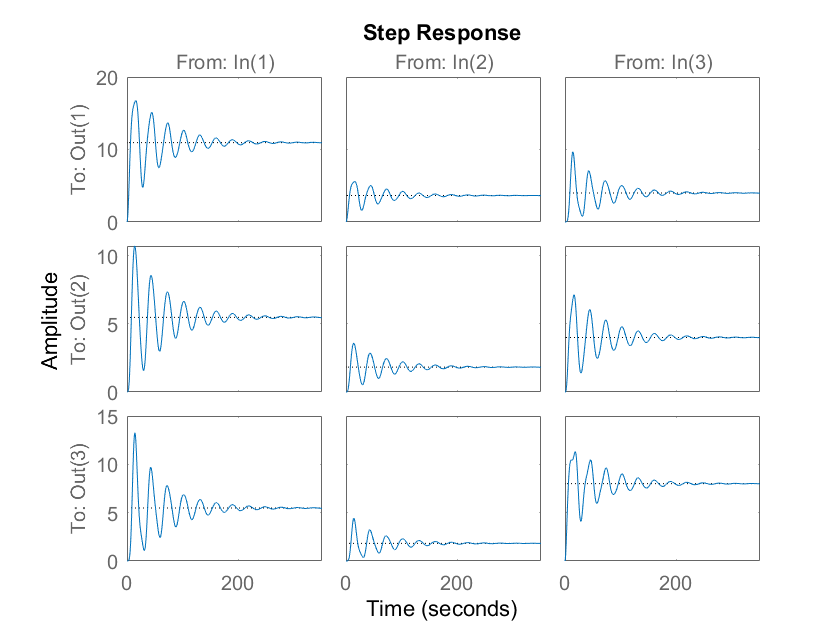

%risposte del sistema in funzione di un gradino applicato rispettivamente
%al primo,secondo e terzo ingresso
step(sys);

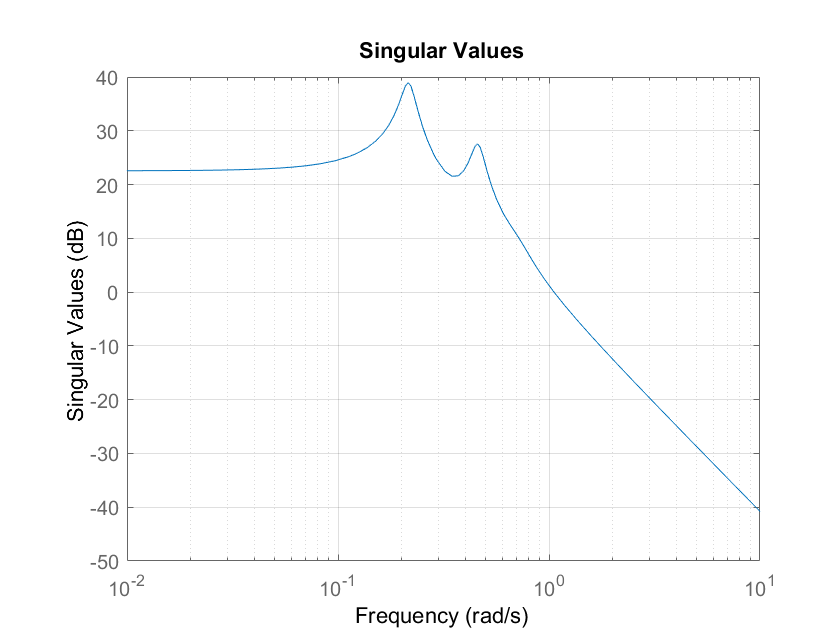


%siccome il terzo ingresso NON è un ingresso di controllo conviene vedere i
%sigma plot separatamente
%un solo sigma plot relativo a ogni ingresso
%tramite i sigma plot posso valutare la norma Hinfinito vista dai segnali
%di ingresso 

figure
sigma(sys(:,1))

grid

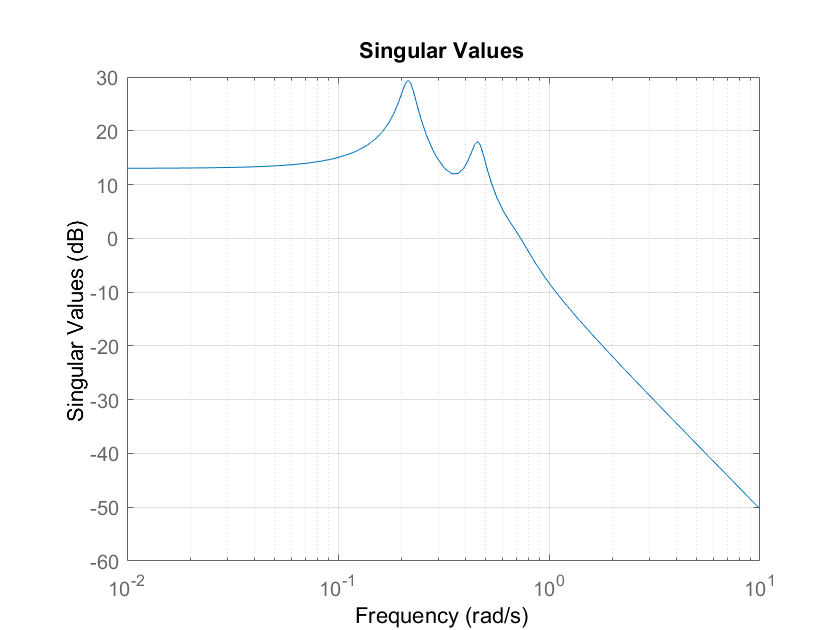

figure
sigma(sys(:,2))

grid

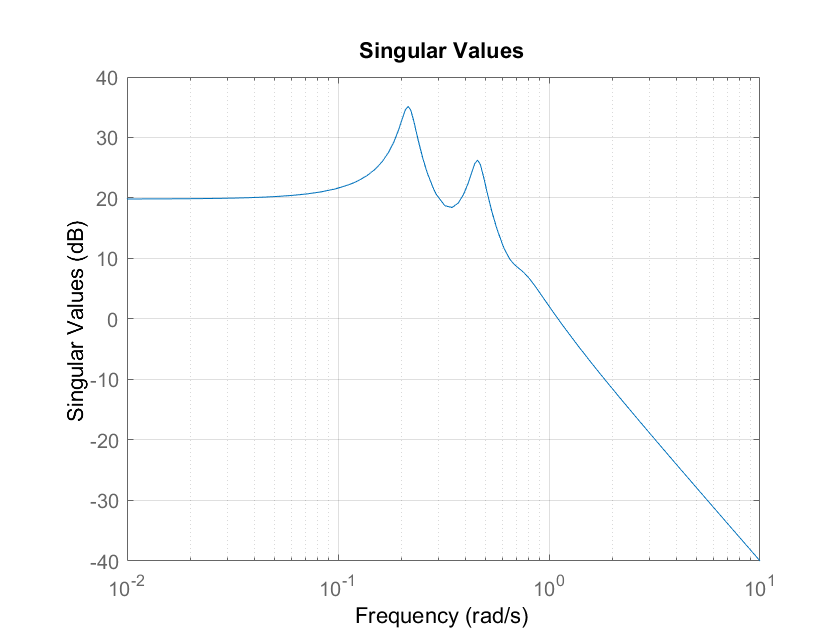


figure
sigma(sys(:,3)) %sigma plot relativo al disturbo

grid


%valore esatto delle tre norme Hinfinito
hinfnorm(sys(:,1)) %norma Hinf vista dall'ingresso di controllo

ans = 88.5547

hinfnorm(sys(:,2))

ans = 29.5182

hinfnorm(sys(:,3)) %norma Hinf vista dall'ingresso di disturbo

ans = 57.2446

hinfnorm(sys)

ans = 109.3412

%SISTEMA AUMENTATO
Aaug=[A zeros(6,2);
     -C(1,:)  0 0;
     -C(2,:)  0 0];
Baug=[B; zeros(2,3)]; %sel sist aumentato considero sempre solo gli ultimi due ingressi (quelli di controllo)
Caug=[C zeros(3,2)];  %aggiungo due righe perchè agg 2 integ le variabili di stato sono aumentate di 2
Daug=D;

sysAug=ss(Aaug,Baug,Caug,Daug);
%Rango matrice di controllabilità sistema aumentato
rank(ctrb(Aaug,Baug(:,2:3))) %considero solo gli ultimi due ingressi (considero solo le ultime due colonne)

ans = 8

r1=50; 
r2=200; 
r1=80; 
r2=200; 
r3=0.25;
Q=r1*(Caug'*Caug)+r2*blkdiag(zeros(6),1,1);
R=r3 * diag([ 0.05*Baug(2,2) Baug(6,3)]); %posso pesare di meno la pos della massa m1??? (mi da problemi con una sov troppo grande 300%
[K,P,e]=lqr(sysAug(:,2:3),Q,R);
K

K =   194.2467   35.7271  112.6972  116.0203   -4.2849    1.0798 -223.5711  -50.9221
    0.5906    0.0540   46.7506   77.9894   14.0442    6.3824    6.2814  -27.5780


P

P = 	1.0e+03 *

    0.0235    0.0024    0.0158    0.0157   -0.0006    0.0001   -0.0303   -0.0073
    0.0024    0.0004    0.0014    0.0015   -0.0001    0.0000   -0.0028   -0.0006
    0.0158    0.0014    1.2944    1.2599   -0.0457    0.0117    0.0652   -0.7151
    0.0157    0.0015    1.2599    2.4493   -0.1183    0.0195    0.2139   -0.8013
   -0.0006   -0.0001   -0.0457   -0.1183    0.0327    0.0035   -0.0115    0.0326
    0.0001    0.0000    0.0117    0.0195    0.0035    0.0016    0.0016   -0.0069
   -0.0303   -0.0028    0.0652    0.2139   -0.0115    0.0016    0.1908   -0.0559
   -0.0073   -0.0006   -0.7151   -0.8013    0.0326   -0.0069   -0.0559    0.6355


e %autovalori a ciclo chiuso del sist.

e =   -0.2585 + 0.6876i
  -0.2585 - 0.6876i
  -0.3574 + 0.0000i
  -1.5783 + 0.0000i
  -2.9727 + 3.0086i
  -2.9727 - 3.0086i
  -4.6260 + 4.7762i
  -4.6260 - 4.7762i


ClLQ=closedLoop(A,B,eye(6),zeros(6,3),K);
olLQ=openLoop(A,B,eye(6),zeros(6,3),K);

## **Observer design**

%PROGETTAZIONE OSSERVATORE
%Non faccio più state feedback ma output feedback ma per farlo dobbiamo
%specificare che sensori abbiamo
%siccome voglio inseguire riferimento sulla pos1 e pos2 -> le devo misurare
%(vediamo se posso misurare solo queste due pos)
%se voglio misurare solo la pos1 e 2 posso prendere solo 2 e seconda riga
%di C
%obsv costruisce la matrice di osservabilità
rank(obsv(A,C(1:2,:))) %mi trovo siccome sist originale di ordine 6

ans = 6

%Il sist. è completamente controllabile
%Quindi posso progettare osservatore (filtro di Kalman dopo) sulla base della misura delle
%pos1 e 2
%prendo gli autovalori a ciclo chiuso del sist, vedo il più veloce e
%mettiamo gli autovalori dell'osservatore una decade dopo (si procede alla costruzione dell’osservatore come assegnamento di
%autovalori sul sistema duale.)
pObs= [-27 -29 -31 -33 -35 -37];
L=place(A',C(1:2,:)',pObs)';
%Scrivo le equazioni dell'osservatore
Aobs=A-L*C(1:2,:);
Bobs=[B(:,2:3) L];  %ci interessa far entrare solo le forze e non il disturbo (U)
%Bobs=[B(:,2:3)-L.*D L];  %L* B-L*D
Cobs=eye(6);
Dobs=zeros(6,4); %Dobs=zeros(6,3);

%KALMAN
%dobbiamo inventare le matrici di covarianza del rumore di misura e del
%rumore del processo
%rumore di misura-> io ho la misura delle posizioni->sensori di posizione->
%stimo la precisone del sensore -> errore di 5cm -> assumo la varianza
%dell'errore di misura di 5/3 cm
%Siccome stiamo caratterizzando l'errore di misura(e di processo) come un
%rumore bianco gaussiano (vedi app pag 3 6 dic)
%(più è larga meglio dal punto di vista del rumore-> rumore distribuito su bande di freq. più elevate)

Rt=sqrt(5e-2/3)/(0.27);
%Rt=sqrt(5e-2/3)/2/(0.27);
%Matrice di covarianza sull'errore di processo
%la scelgo piccola rispetto a Rt (siccome non ho info sul rumore di
%processo) così da avere una buona velocità di convergenza a 0 del valor
%medio dell'errore di stima
%più prendo Q piccolo più il sist tenderà a fidarsi di più del modello e
%quindi la Lk diventa in norma piu piccola
Qt=1e-6*eye(6); %siccome le variabili di stato sono 6 ->Qt=1e-3*eye(6); (cosq +grande e autov piùlenti)
%L è la matrice di guadagno del filtro
%P è la soluzione dell'equazione di riccati del filtro di kalman
sys4Kalman=ss(A,[B(:,2:3) eye(6)],C(1:2,:),zeros(2,8));

[kalmf,Lk,Pk] = kalman((sys4Kalman),Qt,Rt);
norm(Lk)

ans = 6.2359e-04

eig(kalmf)

ans =   -0.1465 + 0.6992i
  -0.1465 - 0.6992i
  -0.0347 + 0.4599i
  -0.0347 - 0.4599i
  -0.0166 + 0.2158i
  -0.0166 - 0.2158i


Rt=sqrt(5e-2/3)/2/(0.3)*1e-6;
Qt=1e-3*eye(6); %più grande rispetto sopra
sys4Kalman=ss(A,[B(:,2:3) eye(6)],C(1:2,:),zeros(2,8));

[kalmf,Lk,Pk] = kalman((sys4Kalman),Qt,Rt);
norm(Lk)

ans = 123.3785

eig(kalmf)%gli autoval. si sono allontanati dall'asse imm. perche io ho aumentato l'errore di processo rispetto l'errore di misura, la misura è diventata più affidabile-> viene utilizzata di più-> filtro più veloce

ans =  -68.1645 + 0.0000i
 -68.1593 + 0.0000i
  -1.0001 + 0.0000i
  -1.0255 + 0.0000i
  -0.1662 + 0.4947i
  -0.1662 - 0.4947i


% BandWidth=1000;
% NoisePower=1e-4/BandWidth;
% Rt=NoisePower;
% Qt=1e-3*eye(6);
% sys4Kalman=ss(A,[B(:,2:3) eye(6)],C(1:2,:),zeros(2,8));
% 
% [kalmf,Lk,Pk] = kalman((sys4Kalman),Qt,Rt);
% norm(Lk)

ans = 180.7926

eig(kalmf)

ans =  -99.9941 + 0.0000i
 -99.9906 + 0.0000i
  -1.0001 + 0.0000i
  -1.0254 + 0.0000i
  -0.1662 + 0.4947i
  -0.1662 - 0.4947i



%estraggo le stime degli stati da kalmf (in quanto le prime due righe di C
%e D corrispondono alle stime delle uscite)
AobsK=kalmf.A;
BobsK=kalmf.B;
CobsK=kalmf.C(3:end,:);
DobsK=kalmf.D(3:end,:);

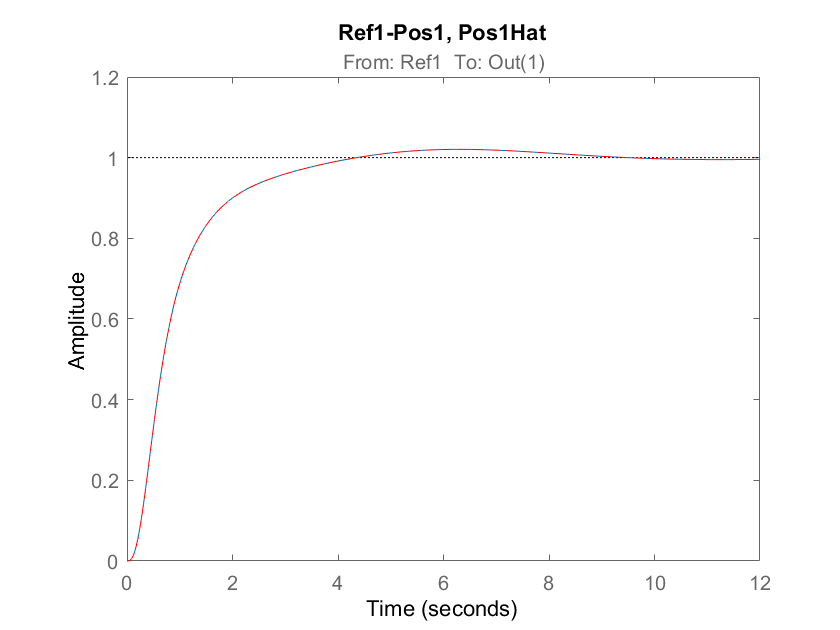

ClLQG=closedLoopLQG(A,B,eye(6),zeros(6,3),K,AobsK,BobsK,CobsK,DobsK);
step(ClLQG(1,1),ClLQG(9,1),'r--') %primo numero usite (pos e sua stima) secondo numero ingresso
%nota: uguali-> errore di stima nullo-> la pres dell'osservatore non mi
%altera la risposta indiciale
title('Ref1-Pos1, Pos1Hat')

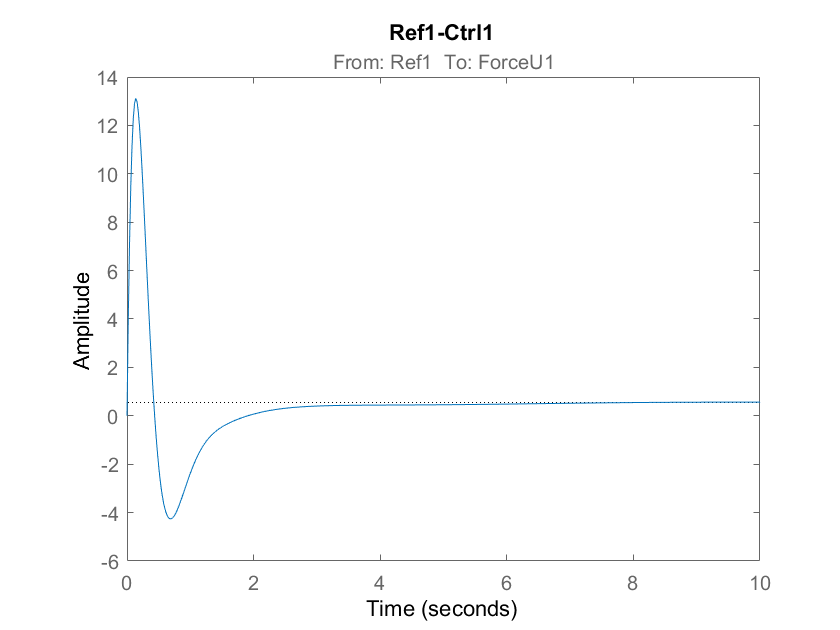


step(ClLQG(7,1)) %risposta indiciale che va dal riferimento all'ingresso di controllo (froceU1)
title('Ref1-Ctrl1')

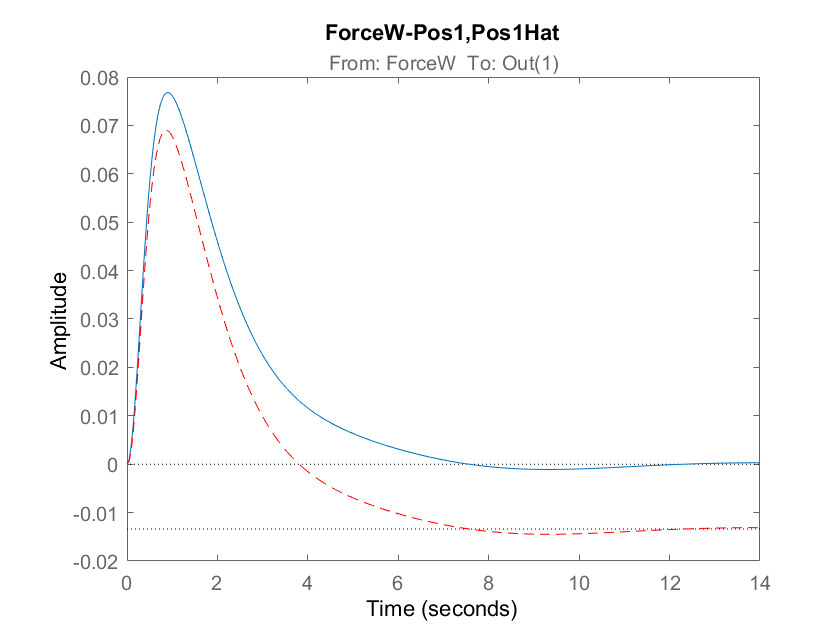


%posso fare la stessa cosa di due grafici fa ma usando come ingresso non il
%riferimento ma il disturbo
%NOTA: se metto un disturbo a gradino la pos1(massam1) converge comunque a
%0 perchè ho l'astatisom. Mentre la stima della pos1 NON va a
%0->perchè quando introduciamo un disturbo, la presenza del disturbo non è
%prevista dall'osservatore-> l'errore di stima NON è in evoluzione libera 
%(guadagno statico tra disturbo e pos1stimata è = a al valore del rosso a
%regime)
step(ClLQG(1,3),ClLQG(9,3),'r--')
title('ForceW-Pos1,Pos1Hat')

%stesso per la pos2 DA RICONTROLLARE
%step(ClLQG(1,2),ClLQG(9,2),'r--')
%title('Ref2-Pos2, Pos2Hat')
%step(ClLQG(8,2)) %risposta indiciale che va dal riferimento all'ingresso di controllo (froceU2)
%title('Ref2-Ctrl2')
%step(ClLQG(2,3),ClLQG(11,3),'r--')
%title('ForceW-Pos1,Pos1Hat')

Closed/open loop system

function clLoop=closedLoop(A,B,C,D,K)
G=ss(A,B,C,D);
%per questo sistema(quello in simulink) posso definire dei nomi per gli ingressi e per le
%uscite
G.InputName={'ForceW','ForceU1','ForceU2'}; %primo ingresso di disturbo e il secondo l'ingresso di controllo
G.OutputName={'Pos1','Vel1','Pos2','Vel2','Pos3','Vel3'};

%Guadagno integrale
Ki1=K(1,7); %primo integratore che agisce sulla prima massa
Ki2=K(2,8); %secondo integratore che agisce sulla seconda massa
%Definisco un sistema che fa da integratore
sysItg1=ss(0,1,Ki1,0);
sysItg1.InputName='errorPos1';
sysItg1.OutputName='IntegralAction1';
%Definisco un sistema che fa da integratore
sysItg2=ss(0,1,Ki2,0);
sysItg2.InputName='errorPos2';
sysItg2.OutputName='IntegralAction2';

%Prendo la matrice di retroazione dello stato dell'impianto
Kf=K(:,1:6);
%Tale sist. non ha variabili di stato perchè è un sist. algebrico
StFeedMatrix=ss([],[],[],Kf); %realizza la relazione Ingresso-uscita y=Kf*u
StFeedMatrix.InputName={'Pos1','Vel1','Pos2','Vel2','Pos3','Vel3'};
StFeedMatrix.OutputName={'StateFeedbackAction1','StateFeedbackAction2'}; %è la parte di retrazione che riguarda l'azione con retroazione di stato


Sum1=sumblk('errorPos1=Ref1-Pos1');
Sum2=sumblk('errorPos2=Ref2-Pos2');
Sum3=sumblk('ForceU1=-IntegralAction1-StateFeedbackAction1');
Sum4=sumblk('ForceU2=-IntegralAction2-StateFeedbackAction2');
%ottengo il sistema a ciclo chiuso tramite il comando connect(gli passo
%tutti i sistemi che mi servono a definire il sist. a ciclo chiuso e gli
%dico quale sono le etichette degli ingressi e delle uscite
clLoop=connect(G,sysItg1,sysItg2,StFeedMatrix,Sum1,Sum2,Sum3,Sum4,{'Ref1','Ref2','ForceW'},{'Pos1','Pos2','Pos3','Vel1','Vel2','Vel3','ForceU1','ForceU2'});
end

%open loop system
function olLoop=openLoop(A,B,C,D,K)
G=ss(A,B,C,D);
%per questo sistema(quello in simulink) posso definire dei nomi per gli ingressi e per le
%uscite
G.InputName={'ForceW','ForceU1','ForceU2'}; %primo ingresso di disturbo e il secondo l'ingresso di controllo
G.OutputName={'Pos1','Vel1','Pos2','Vel2','Pos3','Vel3'};

%Guadagno integrale
Ki1=K(1,7); %primo integratore che agisce sulla prima massa
Ki2=K(2,8); %secondo integratore che agisce sulla seconda massa
%Definisco un sistema che fa da integratore
sysItg1=ss(0,1,Ki1,0);
sysItg1.InputName='errorPos1';
sysItg1.OutputName='IntegralAction1';
%Definisco un sistema che fa da integratore
sysItg2=ss(0,1,Ki2,0);
sysItg2.InputName='errorPos2';
sysItg2.OutputName='IntegralAction2';

%Prendo la matrice di retroazione dello stato dell'impianto
Kf=K(:,1:6);
%Tale sist. non ha variabili di stato perchè è un sist. algebrico
StFeedMatrix=ss([],[],[],Kf); %realizza la relazione Ingresso-uscita y=Kf*u
StFeedMatrix.InputName={'Pos1','Vel1','Pos2','Vel2','Pos3','Vel3'};
StFeedMatrix.OutputName={'StateFeedbackAction1','StateFeedbackAction2'}; %è la parte di retrazione che riguarda l'azione con retroazione di stato


Sum1=sumblk('errorPos1=Ref1-Pos1');
Sum2=sumblk('errorPos2=Ref2-Pos2');
Sum3=sumblk('inCtr1=-IntegralAction1-StateFeedbackAction1'); %inCtr sono le mie uscite
Sum4=sumblk('inCtr2=-IntegralAction2-StateFeedbackAction2');
%Ho aperto il loop in corrispondenza dell'ingresso
%Gli ingressi saranno ingressi Force U1 e U2 e l'uscita e quello che ho a
%valle del controllore
olLoop=connect(G,sysItg1,sysItg2,StFeedMatrix,Sum1,Sum2,Sum3,Sum4,{'ForceU1','ForceU2'},{'inCtr1','inCtr2'});
end

%pOSSO COSTRUIRE SIST. CICLO CHIUSO PORTANDO IN CONTO ANCHE L'OSSERVATORE
%PER OSSERVATORE/KALMAN
%chiudo retroazione con l'osservatore
function clLoop=closedLoopLQG(A,B,C,D,K,Aobs,Bobs,Cobs,Dobs)
G=ss(A,B,C,D);
%per questo sistema(quello in simulink) posso definire dei nomi per gli ingressi e per le
%uscite
G.InputName={'ForceW','ForceU1','ForceU2'}; %primo ingresso di disturbo e il secondo l'ingresso di controllo
G.OutputName={'Pos1','Vel1','Pos2','Vel2','Pos3','Vel3'};

%Guadagno integrale
Ki1=K(1,7); %primo integratore che agisce sulla prima massa
Ki2=K(2,8); %secondo integratore che agisce sulla seconda massa
%Definisco un sistema che fa da integratore
sysItg1=ss(0,1,Ki1,0);
sysItg1.InputName='errorPos1';
sysItg1.OutputName='IntegralAction1';
%Definisco un sistema che fa da integratore
sysItg2=ss(0,1,Ki2,0);
sysItg2.InputName='errorPos2';
sysItg2.OutputName='IntegralAction2';

%Prendo la matrice di retroazione dello stato dell'impianto
Kf=K(:,1:6);
%Tale sist. non ha variabili di stato perchè è un sist. algebrico
StFeedMatrix=ss([],[],[],Kf); %realizza la relazione Ingresso-uscita y=Kf*u
StFeedMatrix.InputName={'Pos1Hat','Vel1Hat','Pos2Hat','Vel2Hat','Pos3Hat','Vel3Hat'};
StFeedMatrix.OutputName={'StateFeedbackAction1','StateFeedbackAction2'}; %è la parte di retrazione che riguarda l'azione con retroazione di stato

observer=ss(Aobs,Bobs,Cobs,Dobs);
%non so se è corretto
observer.InputName={'ForceU1','ForceU2','Pos1','Pos2'}; %ingressi oss. forze applicate e misure che stiamo impiegando
observer.OutputName={'Pos1Hat','Vel1Hat','Pos2Hat','Vel2Hat','Pos3Hat','Vel3Hat'}; %uscite oss.-> stime 6 var. di stato

Sum1=sumblk('errorPos1=Ref1-Pos1');
Sum2=sumblk('errorPos2=Ref2-Pos2');
Sum3=sumblk('ForceU1=-IntegralAction1-StateFeedbackAction1');
Sum4=sumblk('ForceU2=-IntegralAction2-StateFeedbackAction2');
%ottengo il sistema a ciclo chiuso tramite il comando connect(gli passo
%tutti i sistemi che mi servono a definire il sist. a ciclo chiuso e gli
%dico quale sono le etichette degli ingressi e delle uscite
clLoop=connect(G,sysItg1,sysItg2,StFeedMatrix,Sum1,Sum2,Sum3,Sum4,observer,{'Ref1','Ref2','ForceW'},{'Pos1','Pos2','Pos3','Vel1','Vel2','Vel3','ForceU1','ForceU2','Pos1Hat','Vel1Hat','Pos2Hat','Vel2Hat','Pos3Hat','Vel3Hat'});
end


